# 3 | SIMULATED DATA AND EXPLORATORY DATA ANALYSIS

Jay Klopper MD MMed(Surgery)Cum Laude

The George Washington University

## Introduction

In this chapter we take a brief look at how to simulate random values, how to summarize them, and finally, how to visualize them. Once we have access to clean and properly formatted data, our first tasks are always to summarize and visualize the data. This is termed exploratory data analysis (EDA). We do this before applying any statistical tests. EDA gives us many insights into our data including finding unexpected and also incorrect data.

Computers are excellent at generating simulated data. This is very convenient as we learn how to do data analysis as we have control over the generation of random values. This also frees us from the constraints have real-world data that might be difficult to get at the start of our journey and which may also be difficult to work with. In the next chapter, though, we do learn how to import data from a spreadsheet in MATLAB.

The end of the chapter includes a glossary of terms, concepts, and symbols commonly used in data science and statistical analysis.

## Levels of measurement

Data are typically categorized as qualitative or quantitative. **Qualitative** data include those that may be captured by a free-form interview. The researchers might record the interview and later extract meaning or knowledge from the interview following some structured approach. In **quantitative** data analysis we capture random values from a sample space defined for a specific variable. A **sample space**, usually denoted by $\Omega$ or $S$, is a list or interval of values that a variable can take. Random values can be categorized according to their level of measurement. There are two main levels of measurement, **numerical** and** categorical**. Each of these two main levels have two sub-levels of measurement each.

A **ratio-type numerical** level of measurement refers to variables with a sample space that is an interval of real numbers. Depending on the research field, it is typically the most commonly used data type. Ratio-type numerical data is distinctive from interval numerical data, in that the former contains a true $0$, meaning absence. A monetary value of $\$0.00$ is the absence of money. The result of this is that we can consider ratios and state that $\$4$ is twice as much as $\$2$. In contrast, a value of $0$ in **interval type numerical** data does not mean the absence of what is measured. A good example is temperature in degrees Fahrenheit. A value of $0^{\text{o}}$F is not the absence of temperature. Consequently, we cannot state that $100^{\text{o}}$F is twice $50^{\text{o}}$F.

Categorical data are non-numerical data. We might consider a variable such as current smoking status. The sample space for such a variable would be $\Omega = \{ \text{Yes}, \text{No} \}$. There is no order to the elements in the sample space. This is an example of a **nominal categorical** level of measurement. Note that we can encode the values with numbers such as $1$ for Yes and $0$ for No, but these are not actual numbers. In an **ordinal categorical** level of measurement, there is a natural order to the sample space elements. Consider a pain scale. Patients might be asked to state there level of postoperative pain on a scale from $0$ to $10$. There is an order to the sample space elements $\Omega = \{ 0,1,2,3,4, \ldots , 9, 10 \}$, but these are not numbers. There is no fixed difference between each value and we cannot state that the difference in pain experienced between a value of $6$ and $5$ is the same as between $10$ and $9$. We can also not state that someone with a pain score of $4$ has twice as much as someone with a pain score of $2$. irrespective of the sub-type of categorical variables, we refer to each sample space element in a categorical type variables a an individual **class** or **category**.

The level of measurement of a variable determines the summary statistics and the statistical tests that we use.

## Creating random arrays of numbers

The frequency (or count) of occurrence of values or intervals of values that a variable can take can come in certain *patterns*, with some values or intervals of values occurring more frequently than others. These patterns are termed distributions. Distributions can be discrete or continuous. The sample space of a discrete distribution has a countably finite or countable infinite set of values, whereas a continuous distribution has an uncountable infinite set of values. A computer can be tasked to generate random values form such a distribution. We start by considering the discrete uniform distribution.

### Uniform distribution

The sample space of a discrete uniform distribution is a list of values. The probability of randomly selecting any of the sample space elements is the same. Below we take the sample space $S= \{ 50, 51, 52, 53, \ldots , 78,79, 80 \}$and randomly select $5$ values from it. Note that each of the $31$ values in the sample space has an equal probability of being selected. Also note that each of the $5$ values are selected in sequence. After each selection, all of the values in the sample space are again available for random selection. This is termed selection with replacement. To make the random selection reproducible, we seed the pseudo-random number generator with the value $1$ and use the Mersenne Twister algorithm. 

clear variables
% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a discrete uniform distribution (of values 50 through
% 80) assigned to the variable ages
age = randi([50 80],5,1) % Create a 5 row column vector

age =     62
    72
    50
    59
    54


### Normal distribution

The normal distribution is described by a mean and a standard deviation. The curve of the normal distribution is the famous bell-shaped curve. We cannot assign a probability to each value in the sample space of a normal distribution as the values are real numbers. Because of infinite decimal expansion we lose the ability to consider discrete elements in the sample space. Below we slect $5$ values from the standard normal distribution (mean of $0$ and standard deviation of $1$).

% Seed the pseudo-random number generator
rng(1,"twister");
% Five values from the standard normal distribution assigned to the variable
% data
data = normrnd(0,1,[5,1])

data =    -0.6490
    1.1812
   -0.7585
   -1.1096
   -0.8456


### $\chi^{2}$ distribution

The $\chi^{2}$ distribution is described by the degrees of freedom denoted by $\nu$. Below, we select $5$ values from a $\chi^{2}$ distribution with $\nu = 2$.

% Seed the pseudo-random number generator
rng(1,"twister");
% Five values from a chi-square distribution with two degrees of freedom assigned to the variable
% data
data = chi2rnd(2,[5,1])

data =     4.3418
    0.0669
    0.2182
    0.5998
    1.6464


MATLAB has many named distribution and it is a simple task to generate random values from these distributions.

## Summary statistics

We summarize numerical and categorical variable types to gain insight. Such summaries are termed **parameters** when calculated from all observations in a population. When a sample is taken from a population, the same calculated summary values are termed **statistics**.

Summary or descriptive statistics allow us to represent information about a sample of values with single values. There are measures (or summaries) of central tendency. These include the mean, median, and the mode. Measures of dispersion convey information of the spread of values. These include th range (maximum value minus the minimum value), the variance, standard deviation (square root of the variance), the quartiles, and the interquartile range.

Below we create a column vector of $100$ values from a discrete uniform distribution.

clear all
% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a discrete uniform distribution (of values 50 through
% 80) assigned to the variable ages
ages = randi([50 80],100,1);

### Measures of central tendency

#### Sample mean

The arithmetical mean of a sample of numerical data is calculated as shown below.


$$\bar{X} = \frac{1}{n} \sum_{i=1}^{n} x_{i} $$


% Sample mean
mean(ages)

ans = 64.5900

The median is a central value. All numerical values in a data set are listed in ascending order and indexed from $1$ through $n$, where $n$ is the sample size (the number of observations). If $n$ is odd then we take the value at $k^{\text{th}}$ index as calculated below.


$$k=\frac{n-1}{2}+1$$


If $n$ is even, we take the mean of the values at indices $k_{1}$ and $k_{2}$.

$k_{1}=\frac{n}{2}$ and $k_{2}=k_{1}+1$

The median of the values in the `ages` computer variable is calculated below.

% Sample median
median(ages)

ans = 64

To consider the mode, we generate five values from the sample space $S = \{ 0,1 \}$.

% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a list of values (with replacement) assigned to the variable data
data = datasample([0 1],5,'Replace',true)'

data =      0
     1
     0
     0
     0


We calculate the mode, which is clearly $0$, as it occurs most frequently.

% Mode of the data
mode(data)

ans = 0

### Measures of dispersion

#### Variance

The sample variance is calculated below.


$$s^{2}=\frac{{\sum_{i=1}^{n}\left( x_{i} - \bar{X} \right)}^{2}}{n-1}$$


% Sample variance
var(ages,0)

ans = 84.3252

#### Standard deviation

The units in which the variance is calculated is $\text{units}^{2}$. In the case of our example, this is $\text{years}^{2}$, which is non-nonsensical. As such, we take the square roots of the variance to calculate the standard deviation.

% Sample standard deviation
std(ages,0)

ans = 9.1829

#### Minimum and maximum

The minimum and maximum values are self-explanatory.

% Minimum
min(ages)

ans = 50

% Maximum
max(ages)

ans = 80

#### Range

The range is the difference between the maximum and the minimum values.

% Range
max(ages) - min(ages)

ans = 30

#### Quantiles

If the values of a numerical variable are written in ascending order, we can calculate any percentile value from $0\%$ to $100\%$. A percentile of $k\%$ means that $k\%$ of values are less than and $\left( 100 - k \right)\%$ values are more than the calculated value. For this reason the median is the $50^{\text{th}}$ percentile value, also know as the second quartile value. The $0^{\text{th}}$ percentile value is the minimum of $0^{\text{th}}$ quartile value. The $25^{\text{th}}$ percentile is the first quartile value and the  $75^{\text{th}}$ percentile is the third quartile value. Finally, the  $100^{\text{th}}$ percentile is the fourth quartile value.

% First quartile
quantile(ages,0.25)

ans = 56

% Third quartile
quantile(ages,0.75)

ans = 72

The interquartile range is the difference between the third and first quartile values.

% IQR
iqr(ages)

ans = 16

## Data visualization

Data visualization gives us an impression of the patterns or distribution of the data. Different levels of measurement lend themselves to various plot types.

### Visualizing distributions of numerical variables

Histograms and box-and-whisker plots are good visualization of the distribution of numerical data. We start with a histogram of the frequency of values in the `ages` computer variable. Equally sized bins (intervals) are created and the frequency of values within each bin is displayed as the height of the bar for that interval. The bins are half-open intervals. Note that there are no gaps between the bars indicating the fact that the variable is continuous numerical.

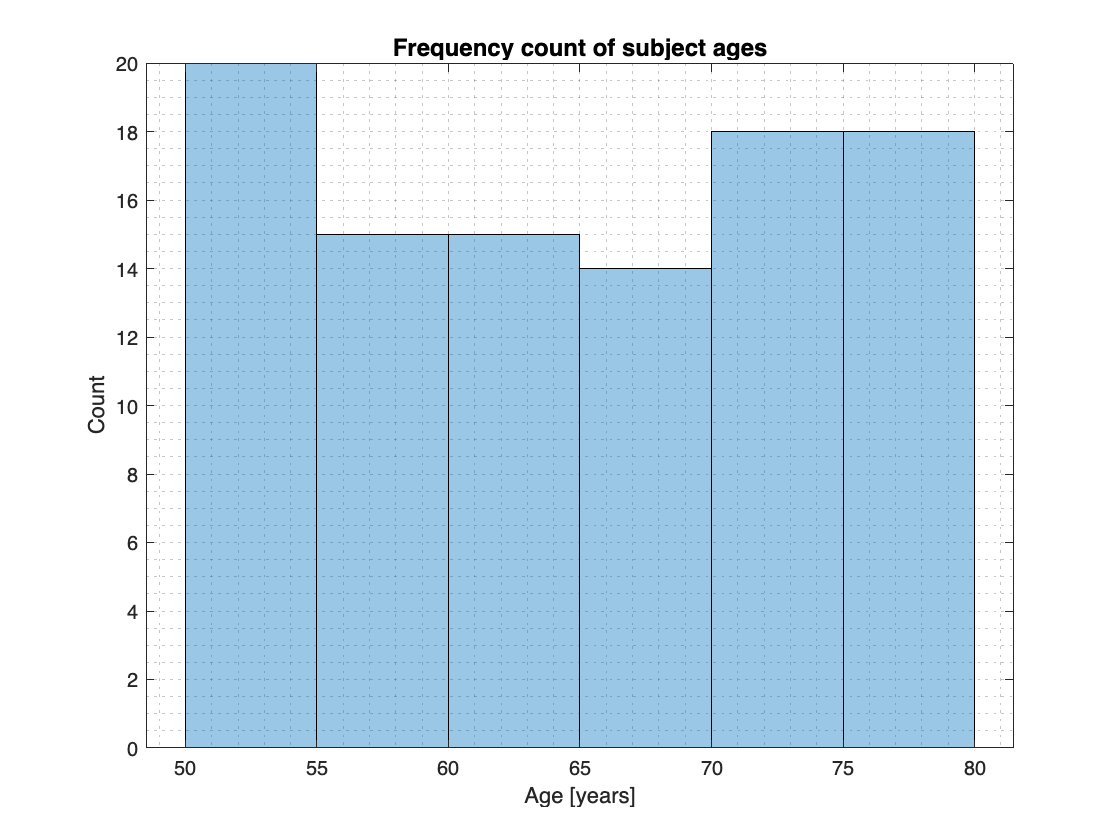

clear variables
% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a discrete uniform distribution (of values 50 through
% 80) assigned to the variable ages
ages = randi([50 80],100,1);
histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4)
xlabel('Age [years]')
ylabel('Count')
title('Frequency count of subject ages',"FontSize",12)
grid minor

A probability histogram divides the frequency of values in each interval by the sample size. This gives us the proportion of values in each interval.

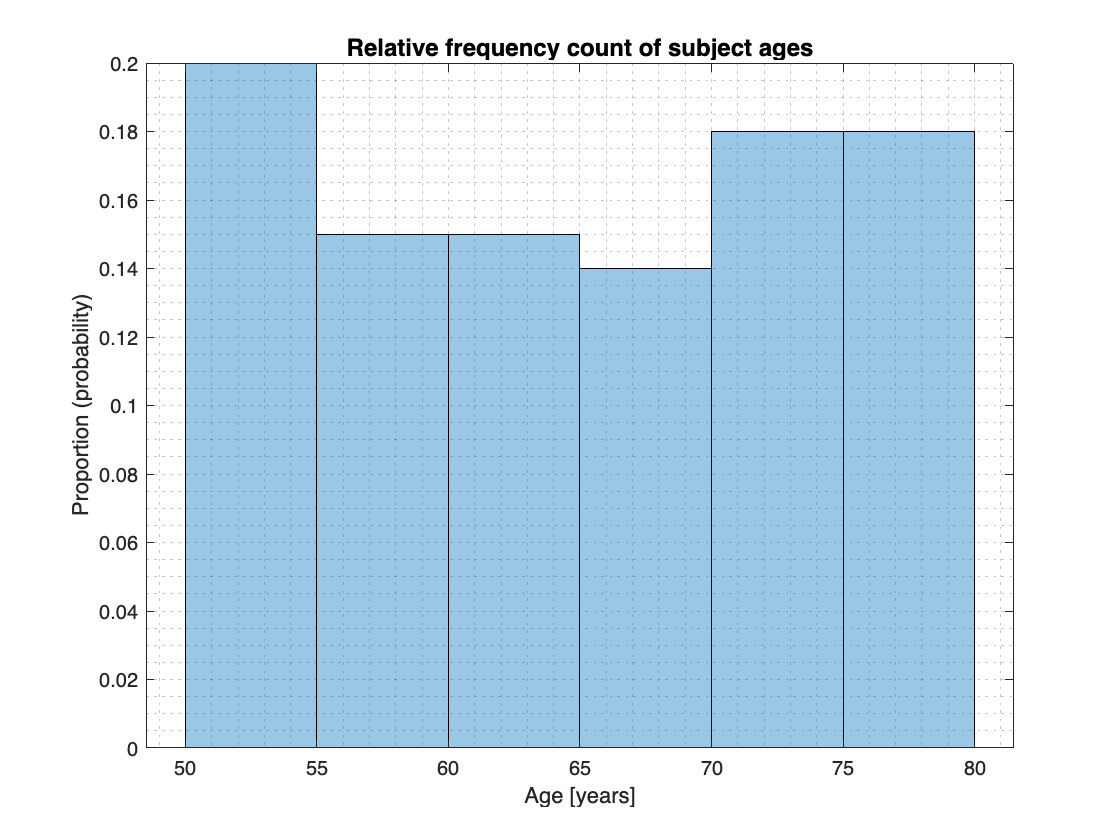

histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4,"Normalization","probability")
xlabel('Age [years]')
ylabel('Proportion (probability)')
title('Relative frequency count of subject ages',"FontSize",12)
grid minor

Dividing the proportion by the length of the interval gives us a probability density.

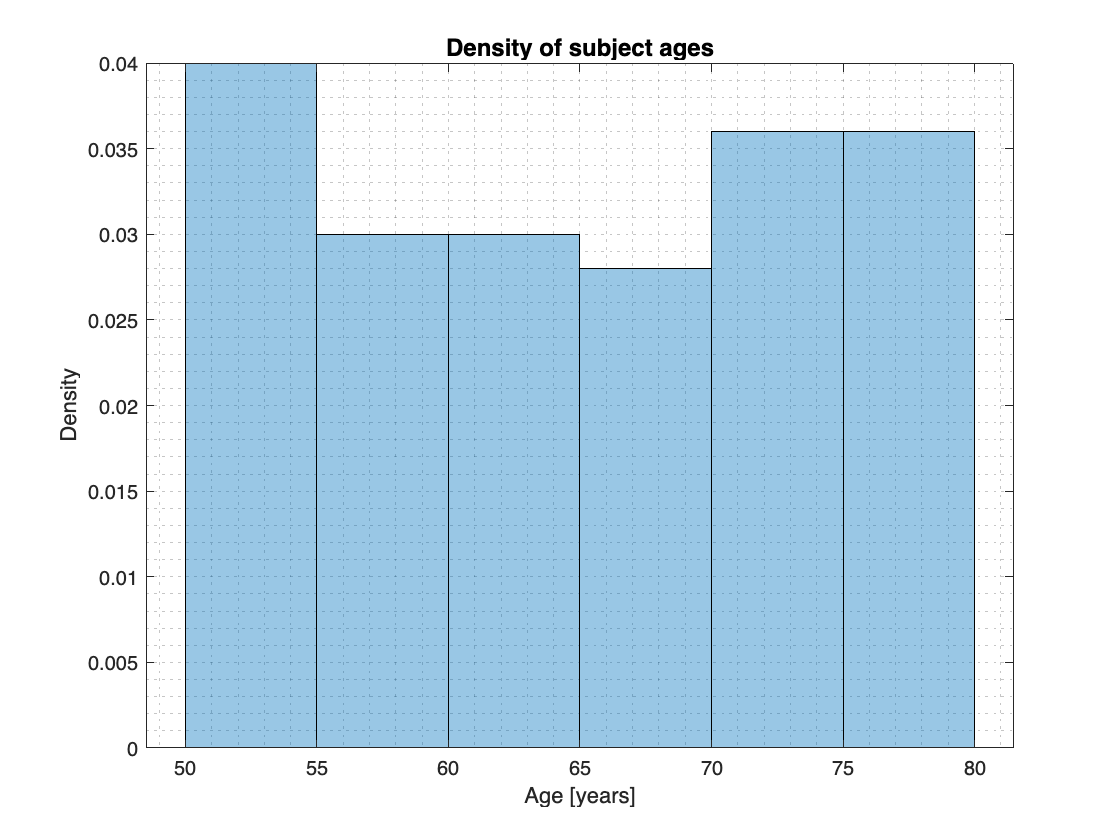

histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4,"Normalization","pdf")
xlabel('Age [years]')
ylabel('Density')
title('Density of subject ages',"FontSize",12)
grid minor

A cumulative distribution histogram adds the probabilities of sequential (left-to-right) intervals.

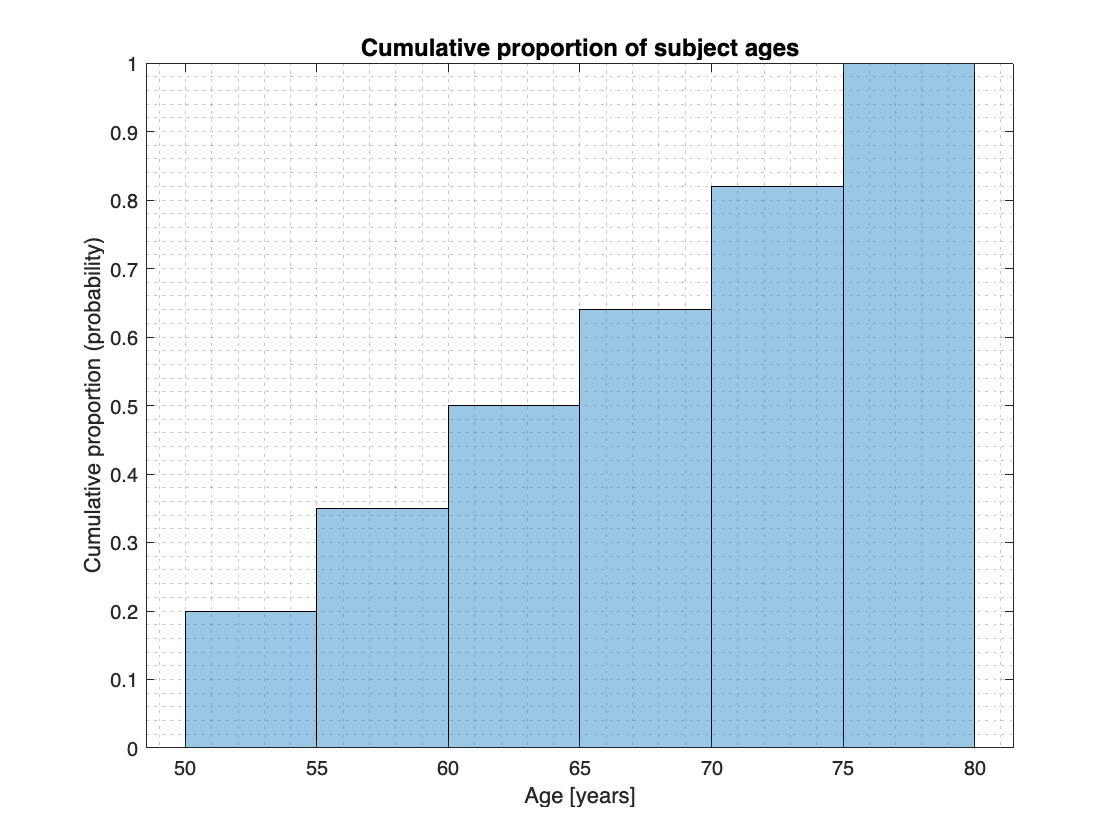

histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4,"Normalization","cdf")
xlabel('Age [years]')
ylabel(['Cumulative proportion (probability)'])
title('Cumulative proportion of subject ages',"FontSize",12)
grid minor

A box-and-whisker plot show the median inside of a rectangle. The lower border of the rectangle is the first quartile and the upper border is the third quartile. If there are no suspected outliers then the lower fence (of the whiskers) is the minimum and the upper fence is the maximum. If there are suspected outliers the lower and upper fences will be at $1.5$ times the interquartile range below and above the first and third quartiles respectively. Suspected outliers will be indicated as individual markers outside the fences.

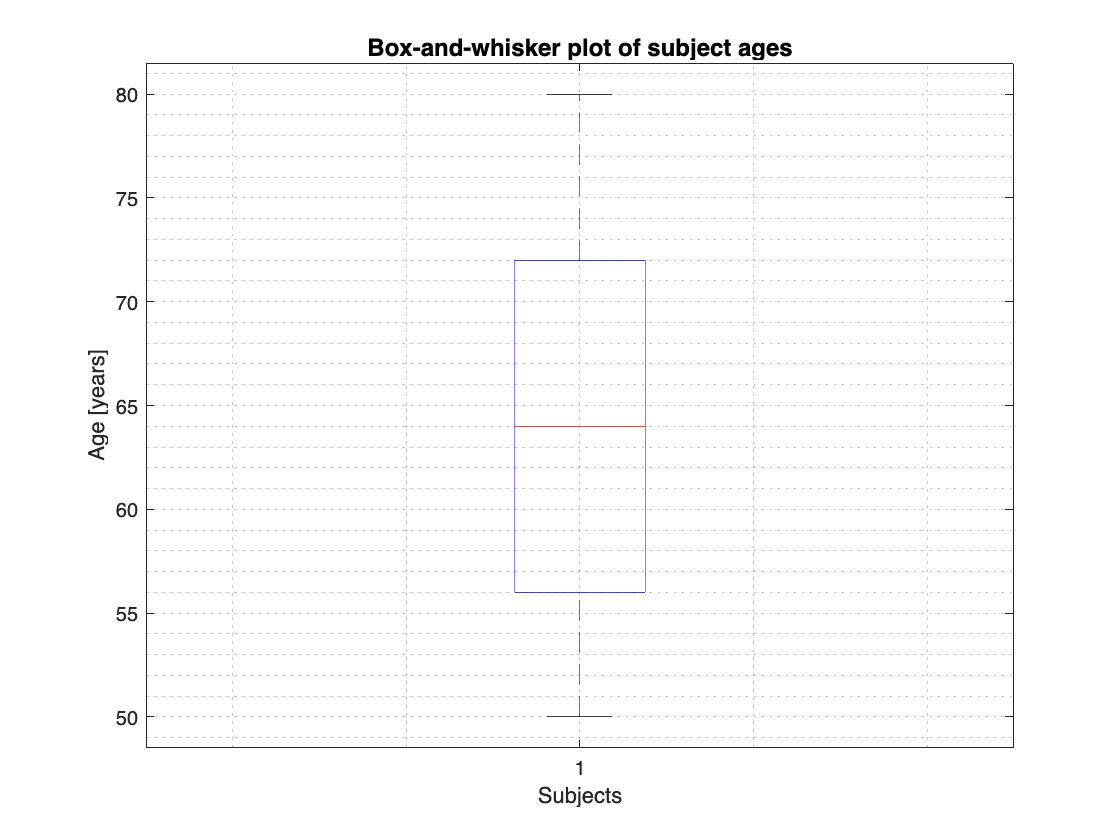

boxplot(ages)
xlabel('Subjects')
ylabel(['Age [years]'])
title('Box-and-whisker plot of subject ages',"FontSize",12)
grid minor

### Visualizing frequencies and relative frequencies of categorical variables

Bar plots show the frequency or relative frequency (proportion) of the classes (categories or levels) of a categorical variable or of discrete variables. Note that there are gaps between the bars indicating visually that the sample space elements of the variable do not form a continuum.

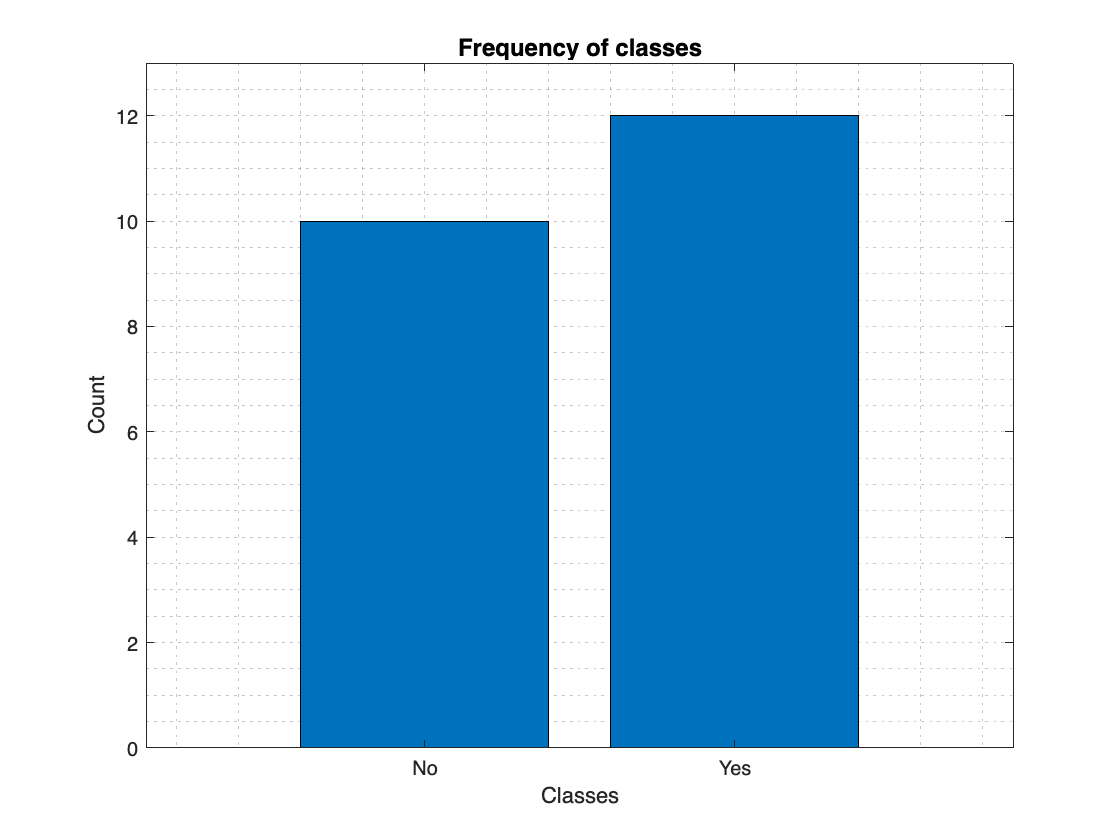

bar(["No","Yes"],[10,12])
xlabel('Classes')
ylabel(['Count'])
title('Frequency of classes',"FontSize",12)
ylim([0,13])
grid minor

### Visualizing the correlation between two numerical variables

A scatter plot visualizes the correlation between two numerical variables. One is placed on the $x$ and one on the perpendicular $y$axis. Below, we visualize the linear relationship between the age and diastolic blood pressure values in our simulated data set.

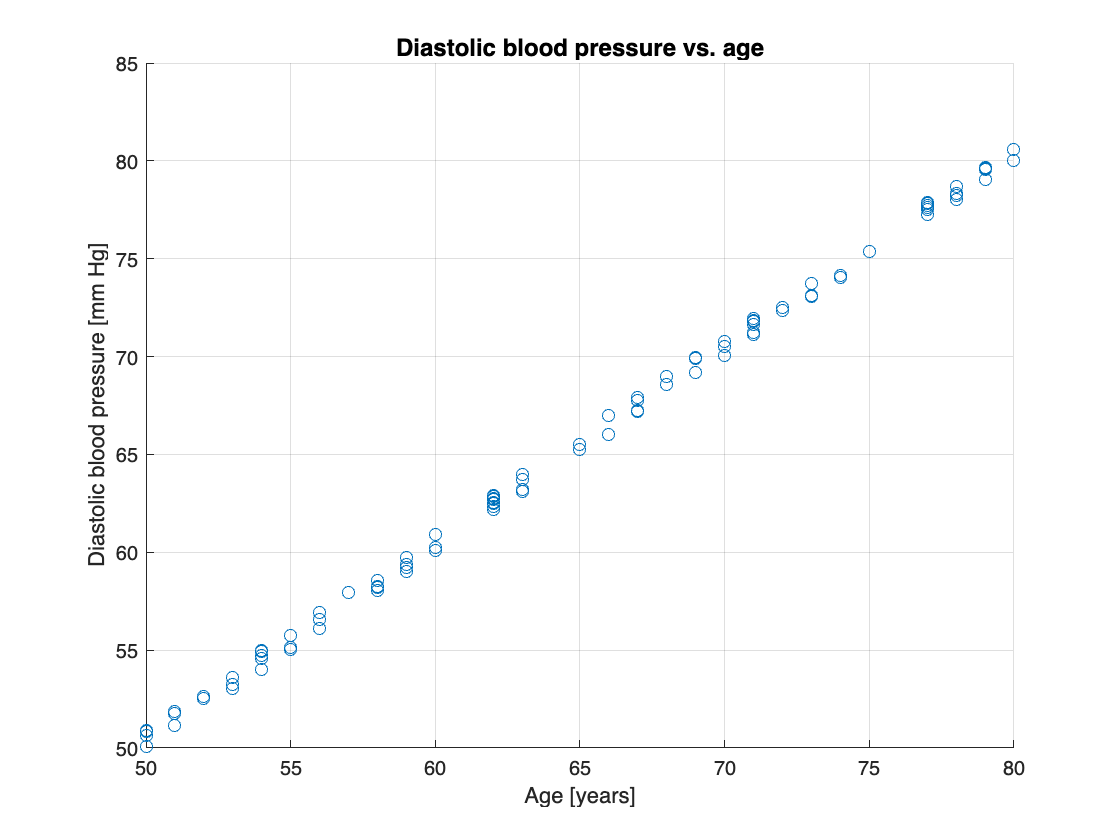

clear variables
% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a discrete uniform distribution (of values 50 through
% 80) assigned to the variable ages
ages = randi([50 80],100,1);
% Random values from a discrete uniform distribution (of values 60 through
% 90) assigned to the variable dbp
dbp = ages + rand(100,1);
scatter(ages,dbp)
xlabel('Age [years]')
ylabel(['Diastolic blood pressure [mm Hg]'])
title('Diastolic blood pressure vs. age',"FontSize",12)
grid on

## Definitions

The aim of data science is to extract information from data. Our goal is most often to learn about a population. We take a representative sample from a population. The sample data is analyzed and the results are used in inference, that is, we apply the result to others in the population. There are meany terms and symbols used in statistical analysis. Some of them are presented in this section

**Population**: The entire group of individuals or items that are the subject of a statistical study.

**Sample**: A subset of the population selected for analysis.

**Experiment**: A procedure carried out to test a hypothesis by observing outcomes under controlled conditions.

**Trial**: A single instance of conducting an experiment.

**Outcome**: The result of a single trial of an experiment.

**Sample Space**: The set of all possible outcomes of an experiment.

**Parameter**: A numerical characteristic of a population.

**Statistic**: A numerical characteristic of a sample used to estimate a population parameter.

**Frequency**: Count of the unique values in a data set.

**Relative frequency **(proportion): The proportion of each unique element in a data set.

**Variable**: A generic term for the name of a specific measurement in each subject in a population or sample, often denoted by the symbol $X$ (irrespective of the variable name).

**Random variable**: Each value in a variable, often denoted by $X_{i}$, where $i$ denotes an index.

**Observation**: A realization (actual value) that a random variable takes.

**Independent and identically distributed** (i.i.d.) random variable: Condition often expected and assumed of a random variable.

Some of the terms and concepts above require more explanation. A collection of random variables is considered independent and identically distributed if each variable has the same probability distribution as the others and all are mutually independent. This means that each random variable in the set is generated under the same conditions and does not influence or depend on the values of the other random variables. As an example, we consider the age of a sample of subject. We might name the variable `age` in a spreadsheet. For statistical analysis we name the variable $X$. We term the age of a random subject a random variable and use the symbol $X_{i}$ for that subject (where $i$ is an index of values $1,2,3, \ldots , n$). An observation is then the actual value usually denoted by $x_{i}$ and we write $X_{i}=x_{i}$ such as $X_{4}=48$ for the fourth subject. The concept of an i.i.d. random variable is fundamental in statistical theory and is often assumed in many statistical methods and models. In our age example, we will them assume that each $X_{i}$ is from the same distribution and each $X_{i}$ is independent of all others random variables in the set.

There are two types of random variables. **Discrete random variables** are random variables that can take on a countable number of distinct values. Examples include the number of students in a class or the outcome of rolling a die. Each value is separate and distinct, with gaps between possible values. Note that we are not considering levels of measurement when referring to random variables. In the case of a categorical variable we count the occurrences of each unique value in the sample space. Here our random variable is $X$, the frequency of a specific unique sample space element. Consider a binary variable which we might name `smoke` and which indicates if a subject is current smoking or not. We assign one of the two elements in the sample space of the variable (which we might denote as `Yes` of `No` as the success class, for instance the `Yes`. The proportion of `Yes` values in the data set is then the random variable $X$). **Continuous random variables** are random variables that can take on an infinite number of possible values within a given range. Examples include the height of individuals or the time it takes to run a marathon. The values form a continuum, and any value within the range is possible.

The following symbols are used in data science.